# Finding bursts from adjusted timestamps

it gets to be easy

units = unique(rasterSpikes.unitID);
minBurstISI = 0.08;
maxBurstISI = 0.16;

burstvars = ["unitID", "Burst", "StartTime", "StopTime", "Duration", 'InterburstInterval', "NumSpikes", "FiringRate", "ISIinBurst"];
burst = table('Size', [0, length(burstvars)+1], 'VariableTypes', [repmat("double", 1, length(burstvars)), "string"], 'VariableNames', [burstvars, "lightCycle"]);

for i = 1:length(units)
    unitdata = rasterSpikes(rasterSpikes.unitID == units(i), :);
    burstIdxs = [];
    inburst = false;
    for j = 1:height(unitdata)
        if j > 1
            prevISI = unitdata.adjustedTimestamp(j) - unitdata.adjustedTimestamp(j-1);
        else
            prevISI = Inf;
        end
        if j < height(unitdata)
            nextISI = unitdata.adjustedTimestamp(j+1) - unitdata.adjustedTimestamp(j);
        else
            nextISI = Inf;
        end

        if (prevISI > minBurstISI) && (nextISI < minBurstISI)
            burstIdxs(end+1, 1) = j;
            inburst = true;
        elseif inburst && (prevISI < maxBurstISI) && (nextISI > maxBurstISI)
            burstIdxs(end, 2) = j;
            inburst = false;
        end
    end

    burstIdxs = burstIdxs(diff(burstIdxs,[],2) > 1,:);

    for j = 1:size(burstIdxs, 1)
        newEntry = table(units(i), j, unitdata.adjustedTimestamp(burstIdxs(j,1)), unitdata.adjustedTimestamp(burstIdxs(j,2)), ...
                         unitdata.adjustedTimestamp(burstIdxs(j,2)) - unitdata.adjustedTimestamp(burstIdxs(j,1)), NaN, ...
                         burstIdxs(j,2) - burstIdxs(j,1) + 1, ...
                         (burstIdxs(j,2) - burstIdxs(j,1) + 1) / (unitdata.adjustedTimestamp(burstIdxs(j,2)) - unitdata.adjustedTimestamp(burstIdxs(j,1))), ...
                         mean(diff(unitdata.adjustedTimestamp(burstIdxs(j,1):burstIdxs(j,2)))), ...
                         unitdata.lightCycle(1), ...
                         'VariableNames', [burstvars, "lightCycle"]);
        if j < size(burstIdxs, 1)
            newEntry.InterburstInterval = unitdata.adjustedTimestamp(burstIdxs(j+1, 1)) - unitdata.adjustedTimestamp(burstIdxs(j,2));
        end
        burst = [burst; newEntry];
    end
end



# Burst Raster! works in chunks

result = burst;
figure;
hold on;

% Define colors and colormap
darkRed = [0.5 0 0];
cmap = jet; % Default colormap for MATLAB (like viridis)
color_limit = 40; % Cap the color scale

% Find unique units for each lightCycle
L_units = unique(result.unitID(result.lightCycle == 'L'));
D_units = unique(result.unitID(result.lightCycle == 'D'));

% Combine the units with L first, then D
combinedUnits = [L_units; D_units];
countUnits = length(combinedUnits) + 1;

% Chunk size for plotting
chunkSize = 10;

% Loop through combined units in chunks
for chunkStart = 1:chunkSize:length(combinedUnits)
    chunkEnd = min(chunkStart + chunkSize - 1, length(combinedUnits));
    currentChunk = combinedUnits(chunkStart:chunkEnd);

    % Loop through the current chunk of units and plot
    for i = 1:length(currentChunk)
        unitRows = result.unitID == currentChunk(i);
        unitTimestamp = result.StartTime(unitRows) / 60; % Convert to minutes
        firingRate = result.FiringRate(unitRows);

        % Cap the firing rate at 50 for coloring
        cappedFiringRate = min(firingRate, color_limit);

        % Normalize firing rate for colormap
        normalizedFiringRate = cappedFiringRate / color_limit;

        % Get colormap color based on firing rate
        colorValues = interp1(linspace(0, 1, size(cmap, 1)), cmap, normalizedFiringRate);

        % Assign colors, vectorized instead of loop
        colors = repmat(darkRed, length(firingRate), 1); % Pre-assign dark red
        lowFiringRateIdx = firingRate <= 50;
        colors(lowFiringRateIdx, :) = colorValues(lowFiringRateIdx, :); % Assign colormap for firing rate <= 50

        % Plot all scatter points in one go, without looping
        scatter(unitTimestamp, repmat(i + chunkStart - 1, size(unitTimestamp)), 200, colors, 'Marker', '|', 'SizeData', 20);
    end

    % Plot vertical lines after scatter plots for each chunk
    line([15, 15], [chunkStart, chunkEnd], 'Color', [0 0.5 0], 'LineWidth', 1.5); % Use darker green
    line([20, 20], [chunkStart, chunkEnd], 'Color', 'r', 'LineWidth', 1.5);
end

xMin = 0;
xMax = 20;
xlim([xMin, xMax]);

xlabel('Time(min)');
ylabel('Unit');
%title('Burst Firing');

yticks(1:length(combinedUnits));
yticklabels(arrayfun(@num2str, combinedUnits, 'UniformOutput', false));
set(gca, 'YDir', 'reverse');

% After you finish plotting all the units

% Set the y-axis limit to match the actual number of units plotted
ylim([1, countUnits - 1]); % Adjust countUnits - 1 to avoid extra space

% Adjust other plot parameters as needed (e.g., margins, aspect ratio)

hold off;

% Create a color bar for the firing rate capped at 50
colormap(cmap);
c = colorbar;
caxis([0 color_limit]);
ylabel(c, 'Firing Rate(hz)');



Sing Burst Rate 

% Ensure 'Unit' and 'lightCycle' are categorical variables
singBlBursts.Unit = categorical(singBlBursts.Unit);

Unable to resolve the name 'singBlBursts.Unit'.

singBlBursts.lightCycle = categorical(singBlBursts.lightCycle);

% Find the unique groups based on 'Unit' and 'lightCycle'
[G, UnitNames, LightCycleNames] = findgroups(singBlBursts.Unit, singBlBursts.lightCycle);

% Apply the numel function to each group to count the number of bursts
totalBursts = splitapply(@numel, singBlBursts.Unit, G);

% Create a table to display the result for spontaneous bursts
blBurstRate = table(UnitNames, LightCycleNames, totalBursts, ...
    'VariableNames', {'Unit', 'lightCycle', 'totalBursts'});
blBurstRate.burstRate = blBurstRate.totalBursts / 900;

% Group by 'lightCycle' and calculate the mean burst rate and standard deviation for spontaneous bursts
[G, lightCycleNames] = findgroups(blBurstRate.lightCycle);
meanBlBurstRate = splitapply(@mean, blBurstRate.burstRate, G);
stdBlBurstRate = splitapply(@std, blBurstRate.burstRate, G);

% Ensure 'Unit' and 'lightCycle' are categorical variables for evoked bursts
singFsBursts.Unit = categorical(singFsBursts.Unit);
singFsBursts.lightCycle = categorical(singFsBursts.lightCycle);

% Find the unique groups based on 'Unit' and 'lightCycle'
[G, UnitNames, LightCycleNames] = findgroups(singFsBursts.Unit, singFsBursts.lightCycle);

% Apply the numel function to each group to count the number of bursts for evoked bursts
totalBursts = splitapply(@numel, singFsBursts.Unit, G);

% Create a table to display the result for evoked bursts
fsBurstRate = table(UnitNames, LightCycleNames, totalBursts, ...
    'VariableNames', {'Unit', 'lightCycle', 'totalBursts'});
fsBurstRate.burstRate = fsBurstRate.totalBursts / 300;

% Group by 'lightCycle' and calculate the mean burst rate and standard deviation for evoked bursts
[G, lightCycleNames] = findgroups(fsBurstRate.lightCycle);
meanFsBurstRate = splitapply(@mean, fsBurstRate.burstRate, G);
stdFsBurstRate = splitapply(@std, fsBurstRate.burstRate, G);

% Convert lightCycleNames to string array for easier interpretation
lightCycleNames = cellstr(lightCycleNames);

% Initialize variables to hold the correct order of "Light" and "Dark" data
lightIdx = strcmp(lightCycleNames, 'L'); % Find index for 'L' (Light)
darkIdx = strcmp(lightCycleNames, 'D');  % Find index for 'D' (Dark)

% Manually assign the correct burst rates and std deviations to Light and Dark
sortedBlBurstRate = [meanBlBurstRate(lightIdx); meanBlBurstRate(darkIdx)];
sortedFsBurstRate = [meanFsBurstRate(lightIdx); meanFsBurstRate(darkIdx)];
sortedBlStdBurstRate = [stdBlBurstRate(lightIdx); stdBlBurstRate(darkIdx)];
sortedFsStdBurstRate = [stdFsBurstRate(lightIdx); stdFsBurstRate(darkIdx)];

% Create a figure for combined bar graph
figure;

% Define the x-axis categories as 'Spontaneous' and 'Evoked'
categoriesInOrder = categorical({'Baseline', 'FootShock'});
categoriesInOrder = reordercats(categoriesInOrder, {'Baseline', 'FootShock'});

% Combine the data for both Light and Dark burst rates into a matrix
combinedBurstRates = [sortedBlBurstRate, sortedFsBurstRate];
combinedStdBurstRates = [sortedBlStdBurstRate, sortedFsStdBurstRate];

% Customize bar colors for Light (Orange) and Dark (Blue)
barColors = [1 0.5 0; 0 0 1]; % Orange for Light, Blue for Dark

% Create a grouped bar graph with custom bar colors
b = bar(categoriesInOrder, combinedBurstRates', 0.6); % Adjusted bar width to 0.6
b(1).FaceColor = 'flat';
b(2).FaceColor = 'flat';

% Set color for Light and Dark bars
b(1).CData = repmat(barColors(1,:), 2, 1); % Orange for Light
b(2).CData = repmat(barColors(2,:), 2, 1); % Blue for Dark

% Hold the current figure to overlay the error bars
hold on;

% Get x-axis positions for the bars
x = [1, 2]; % For 'Spontaneous' and 'Evoked'

% Add thicker error bars for both Light and Dark burst rates
errorbar(x - 0.15, sortedBlBurstRate, sortedBlStdBurstRate, 'k', 'LineStyle', 'none', 'LineWidth', 2); % Light error bars
errorbar(x + 0.15, sortedFsBurstRate, sortedFsStdBurstRate, 'k', 'LineStyle', 'none', 'LineWidth', 2); % Dark error bars

% Add labels and title
xlabel('Burst Type');
ylabel('Burst/sec');
set(gca, 'FontSize', 14); % Adjust 14 to whatever size you prefer

title('Single Channel');

% Add legend for Light and Dark
legend({'Light', 'Dark'}, 'Location', 'northwest');

% Adjust y-axis limits
ylim([0 0.55]); % Adjust according to your needs

% Release the hold on the figure
hold off;


# 16 channel BurstRate

% Ensure 'Unit' and 'lightCycle' are categorical variables
sixBlBursts.Unit = categorical(sixBlBursts.Unit);
sixBlBursts.lightCycle = categorical(sixBlBursts.lightCycle);

% Find the unique groups based on 'Unit' and 'lightCycle'
[G, UnitNames, LightCycleNames] = findgroups(sixBlBursts.Unit, sixBlBursts.lightCycle);

% Apply the numel function to each group to count the number of bursts
totalBursts = splitapply(@numel, sixBlBursts.Unit, G);

% Create a table to display the result for spontaneous bursts
blBurstRate = table(UnitNames, LightCycleNames, totalBursts, ...
    'VariableNames', {'Unit', 'lightCycle', 'totalBursts'});
blBurstRate.burstRate = blBurstRate.totalBursts / 900;

% Group by 'lightCycle' and calculate the mean burst rate and standard deviation for spontaneous bursts
[G, lightCycleNames] = findgroups(blBurstRate.lightCycle);
meanBlBurstRate = splitapply(@mean, blBurstRate.burstRate, G);
stdBlBurstRate = splitapply(@std, blBurstRate.burstRate, G);

% Ensure 'Unit' and 'lightCycle' are categorical variables for evoked bursts
sixFsBursts.Unit = categorical(sixFsBursts.Unit);
sixFsBursts.lightCycle = categorical(sixFsBursts.lightCycle);

% Find the unique groups based on 'Unit' and 'lightCycle'
[G, UnitNames, LightCycleNames] = findgroups(sixFsBursts.Unit, sixFsBursts.lightCycle);

% Apply the numel function to each group to count the number of bursts for evoked bursts
totalBursts = splitapply(@numel, sixFsBursts.Unit, G);

% Create a table to display the result for evoked bursts
fsBurstRate = table(UnitNames, LightCycleNames, totalBursts, ...
    'VariableNames', {'Unit', 'lightCycle', 'totalBursts'});
fsBurstRate.burstRate = fsBurstRate.totalBursts / 300;

% Group by 'lightCycle' and calculate the mean burst rate and standard deviation for evoked bursts
[G, lightCycleNames] = findgroups(fsBurstRate.lightCycle);
meanFsBurstRate = splitapply(@mean, fsBurstRate.burstRate, G);
stdFsBurstRate = splitapply(@std, fsBurstRate.burstRate, G);

% Convert lightCycleNames to string array for easier interpretation
lightCycleNames = cellstr(lightCycleNames);

% Initialize variables to hold the correct order of "Light" and "Dark" data
lightIdx = strcmp(lightCycleNames, 'L'); % Find index for 'L' (Light)
darkIdx = strcmp(lightCycleNames, 'D');  % Find index for 'D' (Dark)

% Manually assign the correct burst rates and std deviations to Light and Dark
sortedBlBurstRate = [meanBlBurstRate(lightIdx); meanBlBurstRate(darkIdx)];
sortedFsBurstRate = [meanFsBurstRate(lightIdx); meanFsBurstRate(darkIdx)];
sortedBlStdBurstRate = [stdBlBurstRate(lightIdx); stdBlBurstRate(darkIdx)];
sortedFsStdBurstRate = [stdFsBurstRate(lightIdx); stdFsBurstRate(darkIdx)];



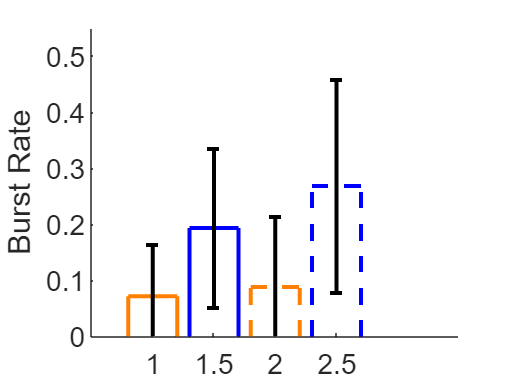

% Define x-axis positions for the bars
x_positions = [1, 1.5, 2, 2.5]; % Adjusted positions for closer bars
bar_width = 0.4; % Width of each bar

% Extract means and standard deviations for plotting
means = [sortedBlBurstRate; sortedFsBurstRate];
sems = [sortedBlStdBurstRate; sortedFsStdBurstRate] ./ sqrt(length(sortedBlBurstRate)); % Standard error

% Define colors
lightColor = [1, 0.5, 0]; % Orange for Light
darkColor = [0, 0, 1];    % Blue for Dark

% Create figure
figure;
hold on;

% Plot outlined bars for Baseline (solid lines)
plot([x_positions(1)-bar_width/2, x_positions(1)+bar_width/2], [means(1), means(1)], 'Color', lightColor, 'LineStyle', '-', 'LineWidth', 2); % Light Baseline - Top line
plot([x_positions(2)-bar_width/2, x_positions(2)+bar_width/2], [means(2), means(2)], 'Color', darkColor, 'LineStyle', '-', 'LineWidth', 2); % Dark Baseline - Top line

% Add vertical edges for baseline bars
plot([x_positions(1)-bar_width/2, x_positions(1)-bar_width/2], [0, means(1)], 'Color', lightColor, 'LineStyle', '-', 'LineWidth', 2); % Left edge - Light BL
plot([x_positions(1)+bar_width/2, x_positions(1)+bar_width/2], [0, means(1)], 'Color', lightColor, 'LineStyle', '-', 'LineWidth', 2); % Right edge - Light BL

plot([x_positions(2)-bar_width/2, x_positions(2)-bar_width/2], [0, means(2)], 'Color', darkColor, 'LineStyle', '-', 'LineWidth', 2); % Left edge - Dark BL
plot([x_positions(2)+bar_width/2, x_positions(2)+bar_width/2], [0, means(2)], 'Color', darkColor, 'LineStyle', '-', 'LineWidth', 2); % Right edge - Dark BL

% Plot outlined bars for Footshock (dashed lines)
plot([x_positions(3)-bar_width/2, x_positions(3)+bar_width/2], [means(3), means(3)], 'Color', lightColor, 'LineStyle', '--', 'LineWidth', 2); % Light Footshock - Top line
plot([x_positions(4)-bar_width/2, x_positions(4)+bar_width/2], [means(4), means(4)], 'Color', darkColor, 'LineStyle', '--', 'LineWidth', 2); % Dark Footshock - Top line

% Add vertical edges for footshock bars
plot([x_positions(3)-bar_width/2, x_positions(3)-bar_width/2], [0, means(3)], 'Color', lightColor, 'LineStyle', '--', 'LineWidth', 2); % Left edge - Light FS
plot([x_positions(3)+bar_width/2, x_positions(3)+bar_width/2], [0, means(3)], 'Color', lightColor, 'LineStyle', '--', 'LineWidth', 2); % Right edge - Light FS

plot([x_positions(4)-bar_width/2, x_positions(4)-bar_width/2], [0, means(4)], 'Color', darkColor, 'LineStyle', '--', 'LineWidth', 2); % Left edge - Dark FS
plot([x_positions(4)+bar_width/2, x_positions(4)+bar_width/2], [0, means(4)], 'Color', darkColor, 'LineStyle', '--', 'LineWidth', 2); % Right edge - Dark FS

% Add error bars
errorbar(x_positions, means, sems, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Formatting
set(gca, 'XTick', x_positions, ...
         'FontSize', 14, 'FontName', 'Arial');
ylabel('Burst Rate');
ylim([0 max(means + sems) * 1.2]); % Adjust y-axis to include error bars
xlim([0.5 3.5]);

hold off;

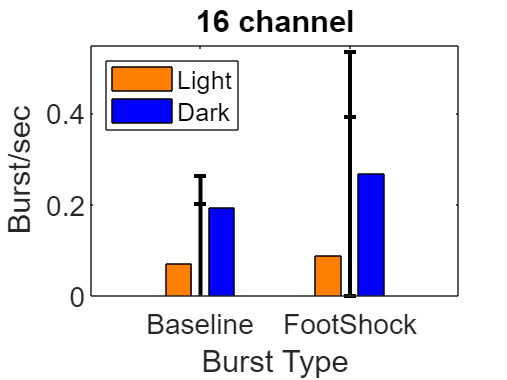

%old Burst rate graph

% Create a figure for combined bar graph
figure;

% Define the x-axis categories as 'Spontaneous' and 'Evoked'
categoriesInOrder = categorical({'Baseline', 'FootShock'});
categoriesInOrder = reordercats(categoriesInOrder, {'Baseline', 'FootShock'});

% Combine the data for both Light and Dark burst rates into a matrix
combinedBurstRates = [sortedBlBurstRate, sortedFsBurstRate];
combinedStdBurstRates = [sortedBlStdBurstRate, sortedFsStdBurstRate];

% Customize bar colors for Light (Orange) and Dark (Blue)
barColors = [1 0.5 0; 0 0 1]; % Orange for Light, Blue for Dark

% Create a grouped bar graph with custom bar colors
b = bar(categoriesInOrder, combinedBurstRates', 0.6); % Adjusted bar width to 0.6
b(1).FaceColor = 'flat';
b(2).FaceColor = 'flat';

% Set color for Light and Dark bars
b(1).CData = repmat(barColors(1,:), 2, 1); % Orange for Light
b(2).CData = repmat(barColors(2,:), 2, 1); % Blue for Dark

% Hold the current figure to overlay the error bars
hold on;

% Get x-axis positions for the bars
x = [1, 2]; % For 'Spontaneous' and 'Evoked'

% Add thicker error bars for both Light and Dark burst rates
errorbar(x - 0.15, sortedBlBurstRate, sortedBlStdBurstRate, 'k', 'LineStyle', 'none', 'LineWidth', 2); % Light error bars
errorbar(x + 0.15, sortedFsBurstRate, sortedFsStdBurstRate, 'k', 'LineStyle', 'none', 'LineWidth', 2); % Dark error bars

% Add labels and title
xlabel('Burst Type');
ylabel('Burst/sec');
set(gca, 'FontSize', 14); % Adjust 14 to whatever size you prefer

% Adjust y-axis limits
ylim([0 0.55]); % Adjust according to your needs
% Release the hold on the figure
hold off;

thirding sing BL bursts

% Assuming burstData is your table and the first column contains unit identifiers
units = unique(singBlBursts.Unit);  % Get unique unit identifiers
selectedBursts = [];  % Initialize an empty array to store selected bursts

for i = 1:length(units)
    unitBursts = singBlBursts(singBlBursts{:, 1} == units(i), :);  % Select rows for the current unit
    numBursts = size(unitBursts, 1);  % Get the number of bursts for this unit
    numToSelect = round(numBursts / 3);  % Calculate one-third of the bursts
    
    % Randomly select bursts for this unit
    selectedIndices = randperm(numBursts, numToSelect);  
    selectedBursts = [selectedBursts; unitBursts(selectedIndices, :)];  % Add selected bursts to the result
end



# Single Channel Burst Properties


% Extract and filter data for Duration
duration_limit = 3;
numSpikes_limit = 50;
interburstInterval_limit = 50;
firingRate_limit = 100;
isi_limit = 100;


L_group_bl = sing3blBursts.Duration(sing3blBursts.lightCycle == 'L');
D_group_bl = sing3blBursts.Duration(sing3blBursts.lightCycle == 'D');
L_group_Fs = singFsBursts.Duration(singFsBursts.lightCycle == 'L');
D_group_Fs = singFsBursts.Duration(singFsBursts.lightCycle == 'D');
L_group_bl = L_group_bl(L_group_bl < duration_limit);
D_group_bl = D_group_bl(D_group_bl < duration_limit);
L_group_Fs = L_group_Fs(L_group_Fs < duration_limit);
D_group_Fs = D_group_Fs(D_group_Fs < duration_limit);

% Extract and filter data for NumSpikes
L_spikes_bl = sing3blBursts.NumSpikes(sing3blBursts.lightCycle == 'L');
D_spikes_bl = sing3blBursts.NumSpikes(sing3blBursts.lightCycle == 'D');
L_spikes_Fs = singFsBursts.NumSpikes(singFsBursts.lightCycle == 'L');
D_spikes_Fs = singFsBursts.NumSpikes(singFsBursts.lightCycle == 'D');
L_spikes_bl = L_spikes_bl(L_spikes_bl < numSpikes_limit);
D_spikes_bl = D_spikes_bl(D_spikes_bl < numSpikes_limit);
L_spikes_Fs = L_spikes_Fs(L_spikes_Fs < numSpikes_limit);
D_spikes_Fs = D_spikes_Fs(D_spikes_Fs < numSpikes_limit);

% Extract and filter data for InterburstInterval
L_interval_bl = sing3blBursts.InterburstInterval(sing3blBursts.lightCycle == 'L');
D_interval_3bl = sing3blBursts.InterburstInterval(sing3blBursts.lightCycle == 'D');
L_interval_Fs = singFsBursts.InterburstInterval(singFsBursts.lightCycle == 'L');
D_interval_Fs = singFsBursts.InterburstInterval(singFsBursts.lightCycle == 'D');
L_interval_bl = L_interval_bl(L_interval_bl < interburstInterval_limit);
D_interval_3bl = D_interval_3bl(D_interval_3bl < interburstInterval_limit);
L_interval_Fs = L_interval_Fs(L_interval_Fs < interburstInterval_limit);
D_interval_Fs = D_interval_Fs(D_interval_Fs < interburstInterval_limit);

% Extract and filter data for FiringRate
L_firingRate_3bl = sing3blBursts.FiringRate(sing3blBursts.lightCycle == 'L');
D_firingRate_3bl = sing3blBursts.FiringRate(sing3blBursts.lightCycle == 'D');
L_firingRate_Fs = singFsBursts.FiringRate(singFsBursts.lightCycle == 'L');
D_firingRate_Fs = singFsBursts.FiringRate(singFsBursts.lightCycle == 'D');
L_firingRate_3bl = L_firingRate_3bl(L_firingRate_3bl < firingRate_limit); % Adjust limit based on your data
D_firingRate_3bl = D_firingRate_3bl(D_firingRate_3bl < firingRate_limit);
L_firingRate_Fs = L_firingRate_Fs(L_firingRate_Fs < firingRate_limit);
D_firingRate_Fs = D_firingRate_Fs(D_firingRate_Fs < firingRate_limit);

% Extract and filter data for ISIinBurst
L_isi_3bl = sing3blBursts.ISIinBurst(sing3blBursts.lightCycle == 'L');
D_isi_bl = sing3blBursts.ISIinBurst(sing3blBursts.lightCycle == 'D');
L_isi_Fs = singFsBursts.ISIinBurst(singFsBursts.lightCycle == 'L');
D_isi_Fs = singFsBursts.ISIinBurst(singFsBursts.lightCycle == 'D');
L_isi_3bl = L_isi_3bl(L_isi_3bl < isi_limit); % Adjust limit based on your data
D_isi_bl = D_isi_bl(D_isi_bl < isi_limit);
L_isi_Fs = L_isi_Fs(L_isi_Fs < isi_limit);
D_isi_Fs = D_isi_Fs(D_isi_Fs < isi_limit);




% Define colors, positions, and box width
bl_colors = [1 0.5 0; 0 0 1];  % Orange for light (L), Blue for dark (D) for BL values
fs_color = [0 0 0];  % Black for FS values
positions = [1, 2];
boxw = 0.1;

% Create figure
figure('Position', [100, 100, 1000, 1200]);  % Adjust size for 5 subplots

% === Duration Subplot ===
subplot(5, 1, 1);
al_goodplot(L_group_bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_group_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_group_bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_group_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Burst Duration (s)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([0, 0.5]);
yticks(0.1:0.2:0.5);
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size

% === NumSpikes Subplot ===
subplot(5, 1, 2);
al_goodplot(L_spikes_bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_spikes_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_spikes_bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_spikes_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Spikes in Burst');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([2.7, 8]);
yticks(4:2:8);
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size

% === InterburstInterval Subplot ===
subplot(5, 1, 3);
al_goodplot(L_interval_bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_interval_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_interval_3bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_interval_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Interburst Interval (s)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([0, 4]);
yticks(2:1:4);
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size



% === FiringRate Subplot ===
subplot(5, 1, 4);
al_goodplot(L_firingRate_3bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_firingRate_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_firingRate_3bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_firingRate_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Firing Rate (Hz)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([5, 60]);  % Adjust limit as needed
yticks(20:20:60); 
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size


% === ISIinBurst Subplot ===
subplot(5, 1, 5);
al_goodplot(L_isi_3bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_isi_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_isi_bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_isi_Fs, positions(2), boxw, fs_color, 'right');
ylabel('ISI in Burst (s)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([0, .15]);  % Adjust limit as needed
yticks(0.05:0.05:0.15); 
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size


hold off;



# Burst for 16 chans

thirding sixteen BL bursts

% Assuming burstData is your table and the first column contains unit identifiers
units = unique(sixBlBursts.Unit);  % Get unique unit identifiers
six3blBursts = [];  % Initialize an empty array to store selected bursts

for i = 1:length(units)
    unitBursts = sixBlBursts(sixBlBursts{:, 1} == units(i), :);  % Select rows for the current unit
    numBursts = size(unitBursts, 1);  % Get the number of bursts for this unit
    numToSelect = round(numBursts / 3);  % Calculate one-third of the bursts
    
    % Randomly select bursts for this unit
    selectedIndices = randperm(numBursts, numToSelect);  
    six3blBursts = [six3blBursts; unitBursts(selectedIndices, :)];  % Add selected bursts to the result
end



# multi Channel Burst Properties

% Extract and filter data for Duration
duration_limit = 10;
numSpikes_limit = 70;
interburstInterval_limit = 70;
firingRate_limit = 100;
isi_limit = 100;


L_group_bl = sixBlBursts.Duration(sixBlBursts.lightCycle == 'L');
D_group_bl = sixBlBursts.Duration(sixBlBursts.lightCycle == 'D');
L_group_Fs = sixFsBursts.Duration(sixFsBursts.lightCycle == 'L');
D_group_Fs = sixFsBursts.Duration(sixFsBursts.lightCycle == 'D');
L_group_bl = L_group_bl(L_group_bl < duration_limit);
D_group_bl = D_group_bl(D_group_bl < duration_limit);
L_group_Fs = L_group_Fs(L_group_Fs < duration_limit);
D_group_Fs = D_group_Fs(D_group_Fs < duration_limit);

% Extract and filter data for NumSpikes
L_spikes_bl = sixBlBursts.NumSpikes(sixBlBursts.lightCycle == 'L');
D_spikes_bl = sixBlBursts.NumSpikes(sixBlBursts.lightCycle == 'D');
L_spikes_Fs = sixFsBursts.NumSpikes(sixFsBursts.lightCycle == 'L');
D_spikes_Fs = sixFsBursts.NumSpikes(sixFsBursts.lightCycle == 'D');
L_spikes_bl = L_spikes_bl(L_spikes_bl < numSpikes_limit);
D_spikes_bl = D_spikes_bl(D_spikes_bl < numSpikes_limit);
L_spikes_Fs = L_spikes_Fs(L_spikes_Fs < numSpikes_limit);
D_spikes_Fs = D_spikes_Fs(D_spikes_Fs < numSpikes_limit);

% Extract and filter data for InterburstInterval
L_interval_bl = sixBlBursts.InterburstInterval(sixBlBursts.lightCycle == 'L');
D_interval_3bl = sixBlBursts.InterburstInterval(sixBlBursts.lightCycle == 'D');
L_interval_Fs = sixFsBursts.InterburstInterval(sixFsBursts.lightCycle == 'L');
D_interval_Fs = sixFsBursts.InterburstInterval(sixFsBursts.lightCycle == 'D');
L_interval_bl = L_interval_bl(L_interval_bl < interburstInterval_limit);
D_interval_3bl = D_interval_3bl(D_interval_3bl < interburstInterval_limit);
L_interval_Fs = L_interval_Fs(L_interval_Fs < interburstInterval_limit);
D_interval_Fs = D_interval_Fs(D_interval_Fs < interburstInterval_limit);

% Extract and filter data for FiringRate
L_firingRate_bl = sixBlBursts.FiringRate(sixBlBursts.lightCycle == 'L');
D_firingRate_bl = sixBlBursts.FiringRate(sixBlBursts.lightCycle == 'D');
L_firingRate_Fs = sixFsBursts.FiringRate(sixFsBursts.lightCycle == 'L');
D_firingRate_Fs = sixFsBursts.FiringRate(sixFsBursts.lightCycle == 'D');
L_firingRate_bl = L_firingRate_bl(L_firingRate_bl < firingRate_limit); % Adjust limit based on your data
D_firingRate_bl = D_firingRate_bl(D_firingRate_3bl < firingRate_limit);
L_firingRate_Fs = L_firingRate_Fs(L_firingRate_Fs < firingRate_limit);
D_firingRate_Fs = D_firingRate_Fs(D_firingRate_Fs < firingRate_limit);

% Extract and filter data for ISIinBurst
L_isi_bl = sixBlBursts.ISI(sixBlBursts.lightCycle == 'L');
D_isi_bl = sixBlBursts.ISI(sixBlBursts.lightCycle == 'D');
L_isi_Fs = sixFsBursts.ISI(sixFsBursts.lightCycle == 'L');
D_isi_Fs = sixFsBursts.ISI(sixFsBursts.lightCycle == 'D');
L_isi_bl = L_isi_bl(L_isi_bl < isi_limit); % Adjust limit based on your data
D_isi_bl = D_isi_bl(D_isi_bl < isi_limit);
L_isi_Fs = L_isi_Fs(L_isi_Fs < isi_limit);
D_isi_Fs = D_isi_Fs(D_isi_Fs < isi_limit);




% Define colors, positions, and box width
bl_colors = [1 0.5 0; 0 0 1];  % Orange for light (L), Blue for dark (D) for BL values
fs_color = [0 0 0];  % Black for FS values
positions = [1, 2];
boxw = 0.1;

% Create figure
figure('Position', [100, 100, 1000, 1200]);  % Adjust size for 5 subplots

% === Duration Subplot ===
subplot(5, 1, 1);
al_goodplot(L_group_bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_group_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_group_bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_group_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Burst Duration (s)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([0, 0.3]);
yticks(0.1:0.1:0.3);
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size

% === NumSpikes Subplot ===
subplot(5, 1, 2);
al_goodplot(L_spikes_bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_spikes_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_spikes_bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_spikes_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Spikes in Burst');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([2.7, 6.5]);
yticks(3:1:6.7);
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size

% === InterburstInterval Subplot ===
subplot(5, 1, 3);
al_goodplot(L_interval_bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_interval_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_interval_3bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_interval_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Interburst Interval (s)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([0, 5]);
yticks(2:1:5);
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size



% === FiringRate Subplot ===
subplot(5, 1, 4);
al_goodplot(L_firingRate_3bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_firingRate_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_firingRate_3bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_firingRate_Fs, positions(2), boxw, fs_color, 'right');
ylabel('Firing Rate (Hz)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([5, 60]);  % Adjust limit as needed
yticks(20:20:60); 
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size


% === ISIinBurst Subplot ===
subplot(5, 1, 5);
al_goodplot(L_isi_3bl, positions(1), boxw, bl_colors(1,:), 'left');
hold on;
al_goodplot(L_isi_Fs, positions(1), boxw, fs_color, 'right');
al_goodplot(D_isi_bl, positions(2), boxw, bl_colors(2,:), 'left');
al_goodplot(D_isi_Fs, positions(2), boxw, fs_color, 'right');
ylabel('ISI in Burst (s)');
set(gca, 'XTick', positions, 'XTickLabel', {'Light', 'Dark'});
ylim([0, .15]);  % Adjust limit as needed
yticks(0.05:0.05:0.15); 
xlim([0.5, 2.8]);
box off;
set(gca, 'FontName', 'Arial', 'FontSize', 12);  % Set font and size


hold off;

Box plots for burst properties

% Define data limits



# Cumulative Distribution, Works! LOVE    Burst Duration

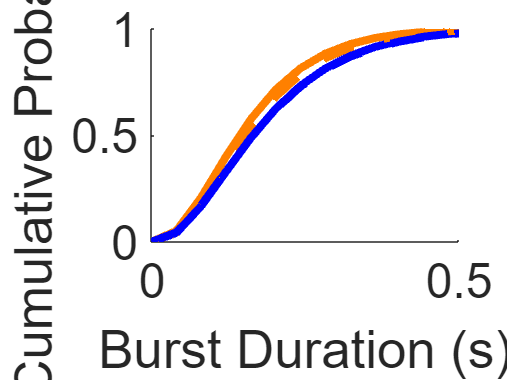

duration_limit = 10;

% Extract and filter data for Duration
L_group_bl = sixBlBursts.Duration(sixBlBursts.lightCycle == 'L');
D_group_bl = sixBlBursts.Duration(sixBlBursts.lightCycle == 'D');
L_group_Fs = sixFsBursts.Duration(sixFsBursts.lightCycle == 'L');
D_group_Fs = sixFsBursts.Duration(sixFsBursts.lightCycle == 'D');

L_group_bl = L_group_bl(L_group_bl < duration_limit);
D_group_bl = D_group_bl(D_group_bl < duration_limit);
L_group_Fs = L_group_Fs(L_group_Fs < duration_limit);
D_group_Fs = D_group_Fs(D_group_Fs < duration_limit);

% Fit Gamma distribution to each group
params_L_bl = gamfit(L_group_bl);
params_D_bl = gamfit(D_group_bl);
params_L_Fs = gamfit(L_group_Fs);
params_D_Fs = gamfit(D_group_Fs);

% Define x values for Gamma CDF
x = linspace(0, 4, 100); % Limit x-axis to 0-4

% Calculate Gamma CDF using fitted parameters
L_group_bl_cdf = gamcdf(x, params_L_bl(1), params_L_bl(2));
D_group_bl_cdf = gamcdf(x, params_D_bl(1), params_D_bl(2));
L_group_Fs_cdf = gamcdf(x, params_L_Fs(1), params_L_Fs(2));
D_group_Fs_cdf = gamcdf(x, params_D_Fs(1), params_D_Fs(2));

% Plot
figure;
hold on;

% Plot Gamma CDFs
plot(x, L_group_bl_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 4); % Light baseline - solid orange
plot(x, D_group_bl_cdf, 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 4); % Dark baseline - solid blue
plot(x, L_group_Fs_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 4); % Light footshock - dashed orange
plot(x, D_group_Fs_cdf, 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 4); % Dark footshock - dashed blue

% Labels, Title, and Legend
set(gca, 'FontSize', 24, 'FontName', 'Arial');
xlabel('Burst Duration (s)');
ylabel('Cumulative Probability');
%legend({'Light Baseline', 'Dark Baseline', 'Light FootShock', 'Dark Footshock'}, 'Location', 'northwest');


xlim([0 .5]); % Adjust x-axis to range from 0 to 4
ylim([0 1]); % Keep y-axis from 0 to 1
yticks([0 0.5 1]);

hold off;

Bar graph for burst duration

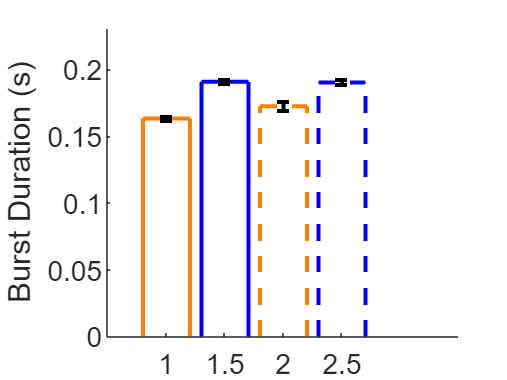

% Extract and filter data for Duration
L_group_bl = sixBlBursts.Duration(sixBlBursts.lightCycle == 'L');
D_group_bl = sixBlBursts.Duration(sixBlBursts.lightCycle == 'D');
L_group_Fs = sixFsBursts.Duration(sixFsBursts.lightCycle == 'L');
D_group_Fs = sixFsBursts.Duration(sixFsBursts.lightCycle == 'D');

% Calculate summary statistics for each group
mean_L_group_bl = mean(L_group_bl);
mean_D_group_bl = mean(D_group_bl);
mean_L_group_Fs = mean(L_group_Fs);
mean_D_group_Fs = mean(D_group_Fs);

% Standard error for error bars
sem_L_group_bl = std(L_group_bl) / sqrt(length(L_group_bl));
sem_D_group_bl = std(D_group_bl) / sqrt(length(D_group_bl));
sem_L_group_Fs = std(L_group_Fs) / sqrt(length(L_group_Fs));
sem_D_group_Fs = std(D_group_Fs) / sqrt(length(D_group_Fs));

% Data for bar graph
means = [mean_L_group_bl, mean_D_group_bl, mean_L_group_Fs, mean_D_group_Fs];
sems = [sem_L_group_bl, sem_D_group_bl, sem_L_group_Fs, sem_D_group_Fs];

% Data for x positions
x_positions = [1, 1.5, 2, 2.5];

% Define bar widths
bar_width = 0.4;

% Create figure
figure;
hold on;

% Plot outlined bars for Baseline (solid lines)
plot([x_positions(1)-bar_width/2, x_positions(1)+bar_width/2], [mean_L_group_bl, mean_L_group_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Light Baseline - Top line
plot([x_positions(2)-bar_width/2, x_positions(2)+bar_width/2], [mean_D_group_bl, mean_D_group_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Dark Baseline - Top line

% Add vertical edges for baseline bars
plot([x_positions(1)-bar_width/2, x_positions(1)-bar_width/2], [0, mean_L_group_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Light BL
plot([x_positions(1)+bar_width/2, x_positions(1)+bar_width/2], [0, mean_L_group_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Light BL

plot([x_positions(2)-bar_width/2, x_positions(2)-bar_width/2], [0, mean_D_group_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Dark BL
plot([x_positions(2)+bar_width/2, x_positions(2)+bar_width/2], [0, mean_D_group_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Dark BL

% Plot outlined bars for Footshock (dashed lines)
plot([x_positions(3)-bar_width/2, x_positions(3)+bar_width/2], [mean_L_group_Fs, mean_L_group_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Light Footshock - Top line
plot([x_positions(4)-bar_width/2, x_positions(4)+bar_width/2], [mean_D_group_Fs, mean_D_group_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Dark Footshock - Top line

% Add vertical edges for footshock bars
plot([x_positions(3)-bar_width/2, x_positions(3)-bar_width/2], [0, mean_L_group_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Light FS
plot([x_positions(3)+bar_width/2, x_positions(3)+bar_width/2], [0, mean_L_group_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Light FS

plot([x_positions(4)-bar_width/2, x_positions(4)-bar_width/2], [0, mean_D_group_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Dark FS
plot([x_positions(4)+bar_width/2, x_positions(4)+bar_width/2], [0, mean_D_group_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Dark FS

% Add error bars
errorbar(x_positions, means, sems, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Formatting
set(gca, 'XTick', x_positions, ...
         'FontSize', 14, 'FontName', 'Arial');
ylabel('Burst Duration (s)');
ylim([0 max(means + sems) * 1.2]); % Adjust y-axis to include error bars
xlim([0.5 3.5]); % Add some space around the bars

hold off;

Spikes Per burst

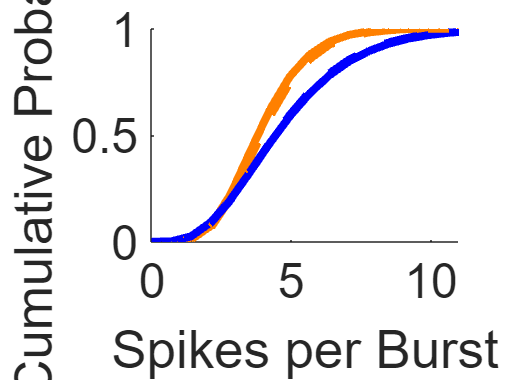

numSpikes_limit = 70;

% Extract and filter data for NumSpikes
L_spikes_bl = sixBlBursts.NumSpikes(sixBlBursts.lightCycle == 'L');
D_spikes_bl = sixBlBursts.NumSpikes(sixBlBursts.lightCycle == 'D');
L_spikes_Fs = sixFsBursts.NumSpikes(sixFsBursts.lightCycle == 'L');
D_spikes_Fs = sixFsBursts.NumSpikes(sixFsBursts.lightCycle == 'D');

% Apply limit to filter out extreme values
L_spikes_bl = L_spikes_bl(L_spikes_bl <= numSpikes_limit);
D_spikes_bl = D_spikes_bl(D_spikes_bl <= numSpikes_limit);
L_spikes_Fs = L_spikes_Fs(L_spikes_Fs <= numSpikes_limit);
D_spikes_Fs = D_spikes_Fs(D_spikes_Fs <= numSpikes_limit);

% Fit Gamma distribution to each group
params_L_bl = gamfit(L_spikes_bl);
params_D_bl = gamfit(D_spikes_bl);
params_L_Fs = gamfit(L_spikes_Fs);
params_D_Fs = gamfit(D_spikes_Fs);

% Define x values for Gamma CDF (adjusted for data range)
x = linspace(0, numSpikes_limit, 100); 

% Calculate Gamma CDF using fitted parameters
L_group_bl_cdf = gamcdf(x, params_L_bl(1), params_L_bl(2));
D_group_bl_cdf = gamcdf(x, params_D_bl(1), params_D_bl(2));
L_group_Fs_cdf = gamcdf(x, params_L_Fs(1), params_L_Fs(2));
D_group_Fs_cdf = gamcdf(x, params_D_Fs(1), params_D_Fs(2));

% Plot
figure;
hold on;

% Plot Gamma CDFs
plot(x, L_group_bl_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 4); % Light baseline - solid orange
plot(x, D_group_bl_cdf, 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 4); % Dark baseline - solid blue
plot(x, L_group_Fs_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 4); % Light footshock - dashed orange
plot(x, D_group_Fs_cdf, 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 4); % Dark footshock - dashed blue

% Labels, Title, and Legend
set(gca, 'FontSize', 24, 'FontName', 'Arial');
xlabel('Spikes per Burst');
ylabel('Cumulative Probability');
%legend({'Light Baseline', 'Dark Baseline', 'Light FootShock', 'Dark Footshock'}, 'Location', 'northwest');

% Formatting
xlim([0 11]); % Adjust x-axis to range from 0 to numSpikes_limit
ylim([0 1]); % Keep y-axis from 0 to 1
yticks([0 0.5 1]);

hold off;

Bar Graph for spikes per burst

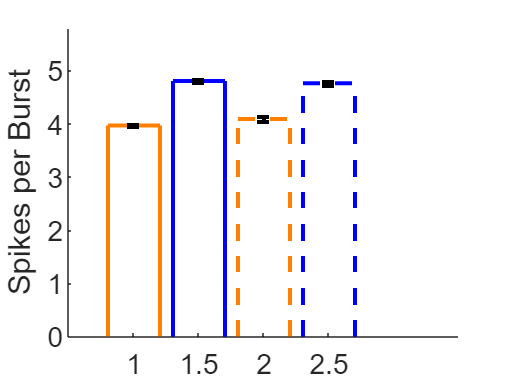

% Calculate summary statistics for each group
mean_L_spikes_bl = mean(L_spikes_bl);
mean_D_spikes_bl = mean(D_spikes_bl);
mean_L_spikes_Fs = mean(L_spikes_Fs);
mean_D_spikes_Fs = mean(D_spikes_Fs);

% Standard error for error bars
sem_L_spikes_bl = std(L_spikes_bl) / sqrt(length(L_spikes_bl));
sem_D_spikes_bl = std(D_spikes_bl) / sqrt(length(D_spikes_bl));
sem_L_spikes_Fs = std(L_spikes_Fs) / sqrt(length(L_spikes_Fs));
sem_D_spikes_Fs = std(D_spikes_Fs) / sqrt(length(D_spikes_Fs));

% Data for bar graph
means = [mean_L_spikes_bl, mean_D_spikes_bl, mean_L_spikes_Fs, mean_D_spikes_Fs];
sems = [sem_L_spikes_bl, sem_D_spikes_bl, sem_L_spikes_Fs, sem_D_spikes_Fs];

% Data for x positions
x_positions = [1, 1.5, 2, 2.5];

% Define bar widths
bar_width = 0.4;

% Create figure
figure;
hold on;

% Plot outlined bars for Baseline (solid lines)
plot([x_positions(1)-bar_width/2, x_positions(1)+bar_width/2], [mean_L_spikes_bl, mean_L_spikes_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Light Baseline - Top line
plot([x_positions(2)-bar_width/2, x_positions(2)+bar_width/2], [mean_D_spikes_bl, mean_D_spikes_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Dark Baseline - Top line

% Add vertical edges for baseline bars
plot([x_positions(1)-bar_width/2, x_positions(1)-bar_width/2], [0, mean_L_spikes_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Light BL
plot([x_positions(1)+bar_width/2, x_positions(1)+bar_width/2], [0, mean_L_spikes_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Light BL

plot([x_positions(2)-bar_width/2, x_positions(2)-bar_width/2], [0, mean_D_spikes_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Dark BL
plot([x_positions(2)+bar_width/2, x_positions(2)+bar_width/2], [0, mean_D_spikes_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Dark BL

% Plot outlined bars for Footshock (dashed lines)
plot([x_positions(3)-bar_width/2, x_positions(3)+bar_width/2], [mean_L_spikes_Fs, mean_L_spikes_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Light Footshock - Top line
plot([x_positions(4)-bar_width/2, x_positions(4)+bar_width/2], [mean_D_spikes_Fs, mean_D_spikes_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Dark Footshock - Top line

% Add vertical edges for footshock bars
plot([x_positions(3)-bar_width/2, x_positions(3)-bar_width/2], [0, mean_L_spikes_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Light FS
plot([x_positions(3)+bar_width/2, x_positions(3)+bar_width/2], [0, mean_L_spikes_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Light FS

plot([x_positions(4)-bar_width/2, x_positions(4)-bar_width/2], [0, mean_D_spikes_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Dark FS
plot([x_positions(4)+bar_width/2, x_positions(4)+bar_width/2], [0, mean_D_spikes_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Dark FS

% Add error bars
errorbar(x_positions, means, sems, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Formatting
set(gca, 'XTick', x_positions, ...
         'FontSize', 14, 'FontName', 'Arial');
ylabel('Spikes per Burst');
ylim([0 max(means + sems) * 1.2]); % Adjust y-axis to include error bars
xlim([0.5 3.5]); % Add some space around the bars

hold off;

INterburst interval

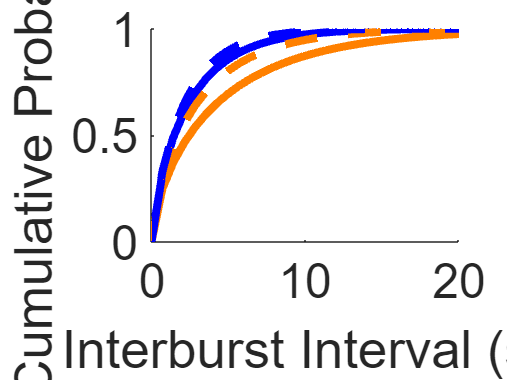


interburstInterval_limit = 70;
% Extract and filter data for InterburstInterval
L_interval_bl = sixBlBursts.InterburstInterval(sixBlBursts.lightCycle == 'L');
D_interval_bl = sixBlBursts.InterburstInterval(sixBlBursts.lightCycle == 'D');
L_interval_Fs = sixFsBursts.InterburstInterval(sixFsBursts.lightCycle == 'L');
D_interval_Fs = sixFsBursts.InterburstInterval(sixFsBursts.lightCycle == 'D');
L_interval_bl = L_interval_bl(L_interval_bl < interburstInterval_limit);
D_interval_bl = D_interval_bl(D_interval_bl < interburstInterval_limit);
L_interval_Fs = L_interval_Fs(L_interval_Fs < interburstInterval_limit);
D_interval_Fs = D_interval_Fs(D_interval_Fs < interburstInterval_limit);

% Fit Gamma distribution to each group
params_L_bl = gamfit(L_interval_bl);
params_D_bl = gamfit(D_interval_bl);
params_L_Fs = gamfit(L_interval_Fs);
params_D_Fs = gamfit(D_interval_Fs);

% Define x values for Gamma CDF (adjusted for data range)
x = linspace(0, interburstInterval_limit, 100); 

% Calculate Gamma CDF using fitted parameters
L_group_bl_cdf = gamcdf(x, params_L_bl(1), params_L_bl(2));
D_group_bl_cdf = gamcdf(x, params_D_bl(1), params_D_bl(2));
L_group_Fs_cdf = gamcdf(x, params_L_Fs(1), params_L_Fs(2));
D_group_Fs_cdf = gamcdf(x, params_D_Fs(1), params_D_Fs(2));

% Plot
figure;
hold on;

% Plot Gamma CDFs
plot(x, L_group_bl_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 4); % Light baseline - solid orange
plot(x, D_group_bl_cdf, 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 4); % Dark baseline - solid blue
plot(x, L_group_Fs_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 4); % Light footshock - dashed orange
plot(x, D_group_Fs_cdf, 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 4); % Dark footshock - dashed blue

% Labels, Title, and Legend
set(gca, 'FontSize', 24, 'FontName', 'Arial');
xlabel('Interburst Interval (s)');
ylabel('Cumulative Probability');
%legend({'Light Baseline', 'Dark Baseline', 'Light FootShock', 'Dark Footshock'}, 'Location', 'northwest');

% Formatting
xlim([0 20]); % Adjust x-axis to range from 0 to numSpikes_limit
ylim([0 1]); % Keep y-axis from 0 to 1
yticks([0 0.5 1]);

hold off;

Bar Graph for Interburst Interval

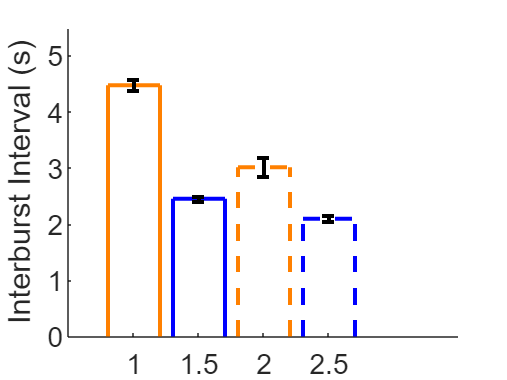

% Calculate summary statistics for each group
mean_L_interval_bl = mean(L_interval_bl);
mean_D_interval_bl = mean(D_interval_bl);
mean_L_interval_Fs = mean(L_interval_Fs);
mean_D_interval_Fs = mean(D_interval_Fs);

% Standard error for error bars
sem_L_interval_bl = std(L_interval_bl) / sqrt(length(L_interval_bl));
sem_D_interval_bl = std(D_interval_bl) / sqrt(length(D_interval_bl));
sem_L_interval_Fs = std(L_interval_Fs) / sqrt(length(L_interval_Fs));
sem_D_interval_Fs = std(D_interval_Fs) / sqrt(length(D_interval_Fs));

% Data for bar graph
means = [mean_L_interval_bl, mean_D_interval_bl, mean_L_interval_Fs, mean_D_interval_Fs];
sems = [sem_L_interval_bl, sem_D_interval_bl, sem_L_interval_Fs, sem_D_interval_Fs];

% Data for x positions
x_positions = [1, 1.5, 2, 2.5];

% Define bar widths
bar_width = 0.4;

% Create figure
figure;
hold on;

% Plot outlined bars for Baseline (solid lines)
plot([x_positions(1)-bar_width/2, x_positions(1)+bar_width/2], [mean_L_interval_bl, mean_L_interval_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Light Baseline - Top line
plot([x_positions(2)-bar_width/2, x_positions(2)+bar_width/2], [mean_D_interval_bl, mean_D_interval_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Dark Baseline - Top line

% Add vertical edges for baseline bars
plot([x_positions(1)-bar_width/2, x_positions(1)-bar_width/2], [0, mean_L_interval_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Light BL
plot([x_positions(1)+bar_width/2, x_positions(1)+bar_width/2], [0, mean_L_interval_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Light BL

plot([x_positions(2)-bar_width/2, x_positions(2)-bar_width/2], [0, mean_D_interval_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Dark BL
plot([x_positions(2)+bar_width/2, x_positions(2)+bar_width/2], [0, mean_D_interval_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Dark BL

% Plot outlined bars for Footshock (dashed lines)
plot([x_positions(3)-bar_width/2, x_positions(3)+bar_width/2], [mean_L_interval_Fs, mean_L_interval_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Light Footshock - Top line
plot([x_positions(4)-bar_width/2, x_positions(4)+bar_width/2], [mean_D_interval_Fs, mean_D_interval_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Dark Footshock - Top line

% Add vertical edges for footshock bars
plot([x_positions(3)-bar_width/2, x_positions(3)-bar_width/2], [0, mean_L_interval_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Light FS
plot([x_positions(3)+bar_width/2, x_positions(3)+bar_width/2], [0, mean_L_interval_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Light FS

plot([x_positions(4)-bar_width/2, x_positions(4)-bar_width/2], [0, mean_D_interval_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Dark FS
plot([x_positions(4)+bar_width/2, x_positions(4)+bar_width/2], [0, mean_D_interval_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Dark FS

% Add error bars
errorbar(x_positions, means, sems, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Formatting
set(gca, 'XTick', x_positions, ...
         'FontSize', 14, 'FontName', 'Arial');
ylabel('Interburst Interval (s)');
ylim([0 max(means + sems) * 1.2]); % Adjust y-axis to include error bars
xlim([0.5 3.5]); % Add some space around the bars

hold off;

Burst Firing Rate

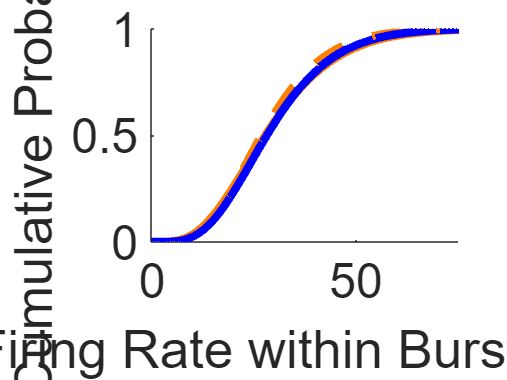

firingRate_limit = 100;
% Extract and filter data for FiringRate
L_firingRate_bl = sixBlBursts.FiringRate(sixBlBursts.lightCycle == 'L');
D_firingRate_bl = sixBlBursts.FiringRate(sixBlBursts.lightCycle == 'D');
L_firingRate_Fs = sixFsBursts.FiringRate(sixFsBursts.lightCycle == 'L');
D_firingRate_Fs = sixFsBursts.FiringRate(sixFsBursts.lightCycle == 'D');
L_firingRate_bl = L_firingRate_bl(L_firingRate_bl < firingRate_limit);
D_firingRate_bl = D_firingRate_bl(D_firingRate_bl < firingRate_limit);
L_firingRate_Fs = L_firingRate_Fs(L_firingRate_Fs < firingRate_limit);
D_firingRate_Fs = D_firingRate_Fs(D_firingRate_Fs < firingRate_limit);

% Fit Gamma distribution to each group
params_L_bl = gamfit(L_firingRate_bl);
params_D_bl = gamfit(D_firingRate_bl);
params_L_Fs = gamfit(L_firingRate_Fs);
params_D_Fs = gamfit(D_firingRate_Fs);

% Define x values for Gamma CDF (adjusted for data range)
x = linspace(0, firingRate_limit, 100); 

% Calculate Gamma CDF using fitted parameters
L_group_bl_cdf = gamcdf(x, params_L_bl(1), params_L_bl(2));
D_group_bl_cdf = gamcdf(x, params_D_bl(1), params_D_bl(2));
L_group_Fs_cdf = gamcdf(x, params_L_Fs(1), params_L_Fs(2));
D_group_Fs_cdf = gamcdf(x, params_D_Fs(1), params_D_Fs(2));

% Plot
figure;
hold on;

% Plot Gamma CDFs
plot(x, L_group_bl_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 4); % Light baseline - solid orange
plot(x, D_group_bl_cdf, 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 4); % Dark baseline - solid blue
plot(x, L_group_Fs_cdf, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 4); % Light footshock - dashed orange
plot(x, D_group_Fs_cdf, 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 4); % Dark footshock - dashed blue

% Labels, Title, and Legend
set(gca, 'FontSize', 24, 'FontName', 'Arial');
xlabel('Firing Rate within Burst (Hz)');
ylabel('Cumulative Probability');
%legend({'Light Baseline', 'Dark Baseline', 'Light FootShock', 'Dark Footshock'}, 'Location', 'northwest');

% Formatting
xlim([0 75]); % Adjust x-axis to range from 0 to numSpikes_limit
ylim([0 1]); % Keep y-axis from 0 to 1
yticks([0 0.5 1]);

hold off;

Bar Graph for firing Rate

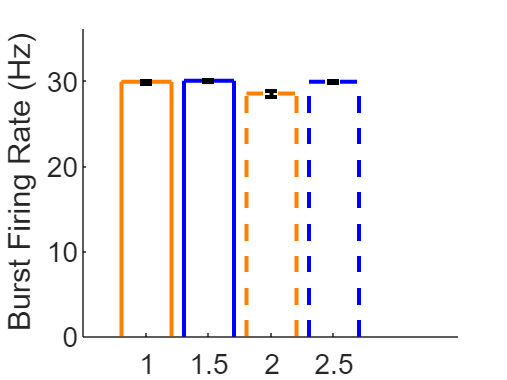

% Calculate summary statistics for each group
mean_L_firingRate_bl = mean(L_firingRate_bl);
mean_D_firingRate_bl = mean(D_firingRate_bl);
mean_L_firingRate_Fs = mean(L_firingRate_Fs);
mean_D_firingRate_Fs = mean(D_firingRate_Fs);

% Standard error for error bars
sem_L_firingRate_bl = std(L_firingRate_bl) / sqrt(length(L_firingRate_bl));
sem_D_firingRate_bl = std(D_firingRate_bl) / sqrt(length(D_firingRate_bl));
sem_L_firingRate_Fs = std(L_firingRate_Fs) / sqrt(length(L_firingRate_Fs));
sem_D_firingRate_Fs = std(D_firingRate_Fs) / sqrt(length(D_firingRate_Fs));

% Data for bar graph
means = [mean_L_firingRate_bl, mean_D_firingRate_bl, mean_L_firingRate_Fs, mean_D_firingRate_Fs];
sems = [sem_L_firingRate_bl, sem_D_firingRate_bl, sem_L_firingRate_Fs, sem_D_firingRate_Fs];

% Data for x positions
x_positions = [1, 1.5, 2, 2.5];

% Define bar widths
bar_width = 0.4;

% Create figure
figure;
hold on;

% Plot outlined bars for Baseline (solid lines)
plot([x_positions(1)-bar_width/2, x_positions(1)+bar_width/2], [mean_L_firingRate_bl, mean_L_firingRate_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Light Baseline - Top line
plot([x_positions(2)-bar_width/2, x_positions(2)+bar_width/2], [mean_D_firingRate_bl, mean_D_firingRate_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Dark Baseline - Top line

% Add vertical edges for baseline bars
plot([x_positions(1)-bar_width/2, x_positions(1)-bar_width/2], [0, mean_L_firingRate_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Light BL
plot([x_positions(1)+bar_width/2, x_positions(1)+bar_width/2], [0, mean_L_firingRate_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Light BL

plot([x_positions(2)-bar_width/2, x_positions(2)-bar_width/2], [0, mean_D_firingRate_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Dark BL
plot([x_positions(2)+bar_width/2, x_positions(2)+bar_width/2], [0, mean_D_firingRate_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Dark BL

% Plot outlined bars for Footshock (dashed lines)
plot([x_positions(3)-bar_width/2, x_positions(3)+bar_width/2], [mean_L_firingRate_Fs, mean_L_firingRate_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Light Footshock - Top line
plot([x_positions(4)-bar_width/2, x_positions(4)+bar_width/2], [mean_D_firingRate_Fs, mean_D_firingRate_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Dark Footshock - Top line

% Add vertical edges for footshock bars
plot([x_positions(3)-bar_width/2, x_positions(3)-bar_width/2], [0, mean_L_firingRate_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Light FS
plot([x_positions(3)+bar_width/2, x_positions(3)+bar_width/2], [0, mean_L_firingRate_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Light FS

plot([x_positions(4)-bar_width/2, x_positions(4)-bar_width/2], [0, mean_D_firingRate_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Dark FS
plot([x_positions(4)+bar_width/2, x_positions(4)+bar_width/2], [0, mean_D_firingRate_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Dark FS

% Add error bars
errorbar(x_positions, means, sems, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Formatting
set(gca, 'XTick', x_positions, ...
         'FontSize', 14, 'FontName', 'Arial');
ylabel('Burst Firing Rate (Hz)');
ylim([0 max(means + sems) * 1.2]); % Adjust y-axis to include error bars
xlim([0.5 3.5]); % Add some space around the bars

hold off;

ISI in burst

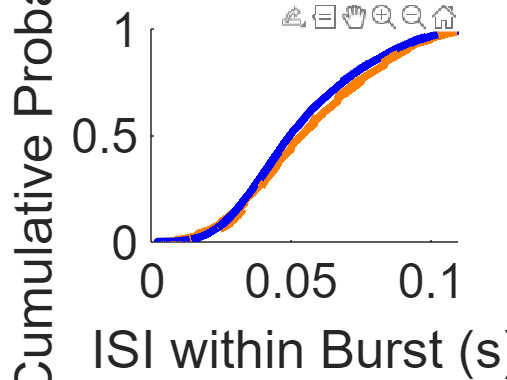

isi_limit = 100; % Set ISI limit for filtering

% Extract and filter data for ISI within Burst
L_isi_bl = sixBlBursts.ISI(sixBlBursts.lightCycle == 'L');
D_isi_bl = sixBlBursts.ISI(sixBlBursts.lightCycle == 'D');
L_isi_Fs = sixFsBursts.ISI(sixFsBursts.lightCycle == 'L');
D_isi_Fs = sixFsBursts.ISI(sixFsBursts.lightCycle == 'D');

% Apply limit to filter extreme values
L_isi_bl = L_isi_bl(L_isi_bl < isi_limit);
D_isi_bl = D_isi_bl(D_isi_bl < isi_limit);
L_isi_Fs = L_isi_Fs(L_isi_Fs < isi_limit);
D_isi_Fs = D_isi_Fs(D_isi_Fs < isi_limit);

% Plot ECDFs
figure;
hold on;

% Compute and plot ECDF for each group
[f_L_bl, x_L_bl] = ecdf(L_isi_bl);
[f_D_bl, x_D_bl] = ecdf(D_isi_bl);
[f_L_Fs, x_L_Fs] = ecdf(L_isi_Fs);
[f_D_Fs, x_D_Fs] = ecdf(D_isi_Fs);

% Plot ECDF curves
plot(x_L_bl, f_L_bl, 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 4); % Light baseline - solid orange
plot(x_D_bl, f_D_bl, 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 4); % Dark baseline - solid blue
plot(x_L_Fs, f_L_Fs, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 4); % Light footshock - dashed orange
plot(x_D_Fs, f_D_Fs, 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 4); % Dark footshock - dashed blue

% Labels, Title, and Legend
set(gca, 'FontSize', 24, 'FontName', 'Arial');
xlabel('ISI within Burst (s)');
ylabel('Cumulative Probability');
%legend({'Light Baseline', 'Dark Baseline', 'Light FootShock', 'Dark Footshock'}, 'Location', 'northwest');

% Formatting
xlim([0 0.11]); % Adjust x-axis to match ISI range
ylim([0 1]); % Set y-axis from 0 to 1
yticks([0 0.5 1]);


hold off;

Bar Graph for ISI

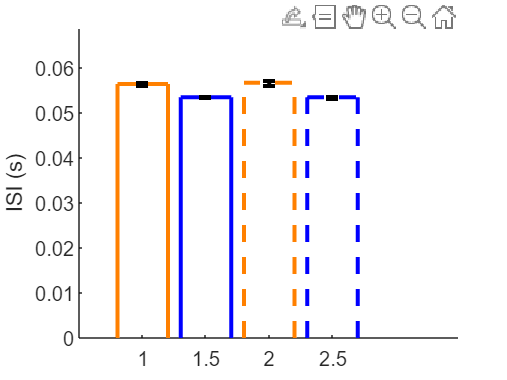

% Calculate summary statistics for each group
mean_L_isi_bl = mean(L_isi_bl);
mean_D_isi_bl = mean(D_isi_bl);
mean_L_isi_Fs = mean(L_isi_Fs);
mean_D_isi_Fs = mean(D_isi_Fs);

% Standard error for error bars
sem_L_isi_bl = std(L_isi_bl) / sqrt(length(L_isi_bl));
sem_D_isi_bl = std(D_isi_bl) / sqrt(length(D_isi_bl));
sem_L_isi_Fs = std(L_isi_Fs) / sqrt(length(L_isi_Fs));
sem_D_isi_Fs = std(D_isi_Fs) / sqrt(length(D_isi_Fs));

% Data for bar graph
means = [mean_L_isi_bl, mean_D_isi_bl, mean_L_isi_Fs, mean_D_isi_Fs];
sems = [sem_L_isi_bl, sem_D_isi_bl, sem_L_isi_Fs, sem_D_isi_Fs];

% Data for x positions
x_positions = [1, 1.5, 2, 2.5];

% Define bar widths
bar_width = 0.4;

% Create figure
figure;
hold on;

% Plot outlined bars for Baseline (solid lines)
plot([x_positions(1)-bar_width/2, x_positions(1)+bar_width/2], [mean_L_isi_bl, mean_L_isi_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Light Baseline - Top line
plot([x_positions(2)-bar_width/2, x_positions(2)+bar_width/2], [mean_D_isi_bl, mean_D_isi_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Dark Baseline - Top line

% Add vertical edges for baseline bars
plot([x_positions(1)-bar_width/2, x_positions(1)-bar_width/2], [0, mean_L_isi_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Light BL
plot([x_positions(1)+bar_width/2, x_positions(1)+bar_width/2], [0, mean_L_isi_bl], 'Color', [1, 0.5, 0], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Light BL

plot([x_positions(2)-bar_width/2, x_positions(2)-bar_width/2], [0, mean_D_isi_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Left edge - Dark BL
plot([x_positions(2)+bar_width/2, x_positions(2)+bar_width/2], [0, mean_D_isi_bl], 'Color', [0, 0, 1], 'LineStyle', '-', 'LineWidth', 2); % Right edge - Dark BL

% Plot outlined bars for Footshock (dashed lines)
plot([x_positions(3)-bar_width/2, x_positions(3)+bar_width/2], [mean_L_isi_Fs, mean_L_isi_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Light Footshock - Top line
plot([x_positions(4)-bar_width/2, x_positions(4)+bar_width/2], [mean_D_isi_Fs, mean_D_isi_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Dark Footshock - Top line

% Add vertical edges for footshock bars
plot([x_positions(3)-bar_width/2, x_positions(3)-bar_width/2], [0, mean_L_isi_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Light FS
plot([x_positions(3)+bar_width/2, x_positions(3)+bar_width/2], [0, mean_L_isi_Fs], 'Color', [1, 0.5, 0], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Light FS

plot([x_positions(4)-bar_width/2, x_positions(4)-bar_width/2], [0, mean_D_isi_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Left edge - Dark FS
plot([x_positions(4)+bar_width/2, x_positions(4)+bar_width/2], [0, mean_D_isi_Fs], 'Color', [0, 0, 1], 'LineStyle', '--', 'LineWidth', 2); % Right edge - Dark FS

% Add error bars
errorbar(x_positions, means, sems, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Formatting
set(gca, 'XTick', x_positions, ...
         'FontSize', 10, 'FontName', 'Arial');
ylabel('ISI (s)');
ylim([0 max(means + sems) * 1.2]); % Adjust y-axis to include error bars
xlim([0.5 3.5]); % Add some space around the bars

hold off;

%IDK
% Define colors
bl_colors = [1 0.5 0; 0 0 1];  % Orange for Light BL, Blue for Dark BL
fs_color = [0 0 0];  % Black for FS values

% Create a figure
figure('Position', [100, 100, 600, 400]);

% Plot CDF for Burst Duration
hold on;

% Check and plot Light BL
if ~isempty(L_group_bl)
    [X1, F1] = ecdf(L_group_bl);
    plot(X1, F1, 'Color', bl_colors(1, :), 'LineWidth', 2);
end

% Check and plot Dark BL
if ~isempty(D_group_bl)
    [X2, F2 = ecdf(D_group_bl);

Unsupported use of the '=' operator. To compare values for equality, use '=='. To specify name-value arguments, check that name is a valid identifier with no surrounding quotes.

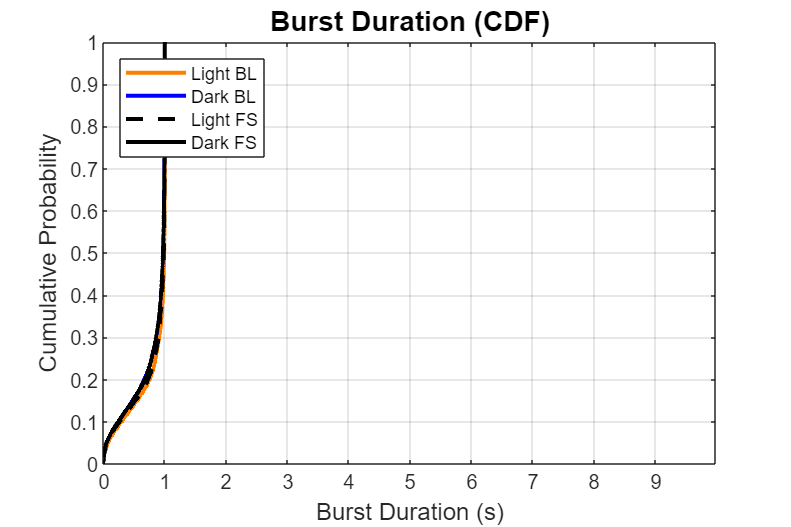

    plot(X2, F2, 'Color', bl_colors(2, :), 'LineWidth', 2);
end

% Check and plot Light FS
if ~isempty(L_group_Fs)
    [X3, F3] = ecdf(L_group_Fs);
    plot(X3, F3, 'Color', fs_color, 'LineWidth', 2, 'LineStyle', '--');
end

% Check and plot Dark FS
if ~isempty(D_group_Fs)
    [X4, F4] = ecdf(D_group_Fs);
    plot(X4, F4, 'Color', fs_color, 'LineWidth', 2);
end

% Customize the plot
title('Burst Duration (CDF)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Burst Duration (s)', 'FontSize', 12);
ylabel('Cumulative Probability', 'FontSize', 12);
legend({'Light BL', 'Dark BL', 'Light FS', 'Dark FS'}, 'Location', 'northwest');
xlim([0 max([L_group_bl; D_group_bl; L_group_Fs; D_group_Fs])]);  % Adjust X-axis to data
ylim([0 1]);  % Ensure cumulative probability goes from 0 to 1
grid on;
box on;
hold off;


Cumulative distribution...gross

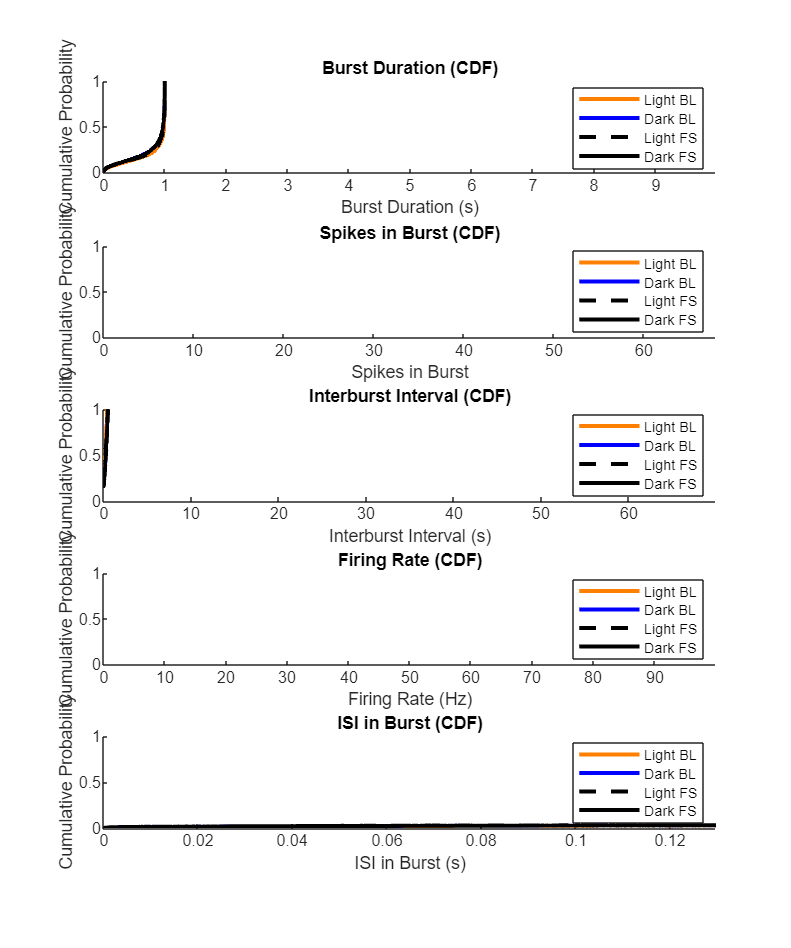

% Define colors
bl_colors = [1 0.5 0; 0 0 1];  % Orange for BL, Blue for BL (group 2)
fs_color = [0 0 0];  % Black for FS values

% Create figure
figure('Position', [100, 100, 1000, 1200]);  % Adjust size for 5 subplots

% === Duration CDF ===
subplot(5, 1, 1);
hold on;
[X1, F1] = ecdf(L_group_bl);  % Light BL
plot(X1, F1, 'Color', bl_colors(1, :), 'LineWidth', 2);
[X2, F2] = ecdf(D_group_bl);  % Dark BL
plot(X2, F2, 'Color', bl_colors(2, :), 'LineWidth', 2);
[X3, F3] = ecdf(L_group_Fs);  % Light FS
plot(X3, F3, 'Color', fs_color, 'LineWidth', 2, 'LineStyle', '--');
[X4, F4] = ecdf(D_group_Fs);  % Dark FS
plot(X4, F4, 'Color', fs_color, 'LineWidth', 2);
title('Burst Duration (CDF)');
xlabel('Burst Duration (s)');
ylabel('Cumulative Probability');
legend({'Light BL', 'Dark BL', 'Light FS', 'Dark FS'}, 'Location', 'best');
xlim([0 max([L_group_bl; D_group_bl; L_group_Fs; D_group_Fs])]);
ylim([0 1]);
hold off;

% === NumSpikes CDF ===
subplot(5, 1, 2);
hold on;
[X1, F1] = ecdf(L_spikes_bl);  % Light BL
plot(X1, F1, 'Color', bl_colors(1, :), 'LineWidth', 2);
[X2, F2] = ecdf(D_spikes_bl);  % Dark BL
plot(X2, F2, 'Color', bl_colors(2, :), 'LineWidth', 2);
[X3, F3] = ecdf(L_spikes_Fs);  % Light FS
plot(X3, F3, 'Color', fs_color, 'LineWidth', 2, 'LineStyle', '--');
[X4, F4] = ecdf(D_spikes_Fs);  % Dark FS
plot(X4, F4, 'Color', fs_color, 'LineWidth', 2);
title('Spikes in Burst (CDF)');
xlabel('Spikes in Burst');
ylabel('Cumulative Probability');
legend({'Light BL', 'Dark BL', 'Light FS', 'Dark FS'}, 'Location', 'best');
xlim([0 max([L_spikes_bl; D_spikes_bl; L_spikes_Fs; D_spikes_Fs])]);
ylim([0 1]);
hold off;

% === Interburst Interval CDF ===
subplot(5, 1, 3);
hold on;
[X1, F1] = ecdf(L_interval_bl);  % Light BL
plot(X1, F1, 'Color', bl_colors(1, :), 'LineWidth', 2);
[X2, F2] = ecdf(D_interval_bl);  % Dark BL
plot(X2, F2, 'Color', bl_colors(2, :), 'LineWidth', 2);
[X3, F3] = ecdf(L_interval_Fs);  % Light FS
plot(X3, F3, 'Color', fs_color, 'LineWidth', 2, 'LineStyle', '--');
[X4, F4] = ecdf(D_interval_Fs);  % Dark FS
plot(X4, F4, 'Color', fs_color, 'LineWidth', 2);
title('Interburst Interval (CDF)');
xlabel('Interburst Interval (s)');
ylabel('Cumulative Probability');
legend({'Light BL', 'Dark BL', 'Light FS', 'Dark FS'}, 'Location', 'best');
xlim([0 max([L_interval_bl; D_interval_bl; L_interval_Fs; D_interval_Fs])]);
ylim([0 1]);
hold off;

% === FiringRate CDF ===
subplot(5, 1, 4);
hold on;
[X1, F1] = ecdf(L_firingRate_bl);  % Light BL
plot(X1, F1, 'Color', bl_colors(1, :), 'LineWidth', 2);
[X2, F2] = ecdf(D_firingRate_bl);  % Dark BL
plot(X2, F2, 'Color', bl_colors(2, :), 'LineWidth', 2);
[X3, F3] = ecdf(L_firingRate_Fs);  % Light FS
plot(X3, F3, 'Color', fs_color, 'LineWidth', 2, 'LineStyle', '--');
[X4, F4] = ecdf(D_firingRate_Fs);  % Dark FS
plot(X4, F4, 'Color', fs_color, 'LineWidth', 2);
title('Firing Rate (CDF)');
xlabel('Firing Rate (Hz)');
ylabel('Cumulative Probability');
legend({'Light BL', 'Dark BL', 'Light FS', 'Dark FS'}, 'Location', 'best');
xlim([0 max([L_firingRate_bl; D_firingRate_bl; L_firingRate_Fs; D_firingRate_Fs])]);
ylim([0 1]);
hold off;

% === ISIinBurst CDF ===
subplot(5, 1, 5);
hold on;
[X1, F1] = ecdf(L_isi_bl);  % Light BL
plot(X1, F1, 'Color', bl_colors(1, :), 'LineWidth', 2);
[X2, F2] = ecdf(D_isi_bl);  % Dark BL
plot(X2, F2, 'Color', bl_colors(2, :), 'LineWidth', 2);
[X3, F3] = ecdf(L_isi_Fs);  % Light FS
plot(X3, F3, 'Color', fs_color, 'LineWidth', 2, 'LineStyle', '--');
[X4, F4] = ecdf(D_isi_Fs);  % Dark FS
plot(X4, F4, 'Color', fs_color, 'LineWidth', 2);
title('ISI in Burst (CDF)');
xlabel('ISI in Burst (s)');
ylabel('Cumulative Probability');
legend({'Light BL', 'Dark BL', 'Light FS', 'Dark FS'}, 'Location', 'best');
xlim([0 max([L_isi_bl; D_isi_bl; L_isi_Fs; D_isi_Fs])]);
ylim([0 1]);
hold off;